fixedLength = 1000;
testAnomalousData = reshape(abnormalwaveformData, testnumFiles, fixedLength);
testHealthyData = reshape(testwaveformData,testnumFiles,fixedLength);

% Predict using the trained network
predictedHealthy= predict(net, testHealthyData);
predictedAnomalous = predict(net, testAnomalousData);

% Compute reconstruction error
mseErrorHealthy = mean((testHealthyData - predictedHealthy).^2, 2);
rmseErrorHealthy = sqrt(mseErrorHealthy);

% Display statistics
fprintf("Mean Reconstruction Error (MSE) on Anomalous Data: %.6f\n", mean(mseErrorHealthy));

Mean Reconstruction Error (MSE) on Anomalous Data: 0.000497


fprintf("Root Mean Reconstruction Error (RMSE) on Anomalous Data: %.6f\n", mean(rmseErrorAnomalous));

Root Mean Reconstruction Error (RMSE) on Anomalous Data: 0.077604


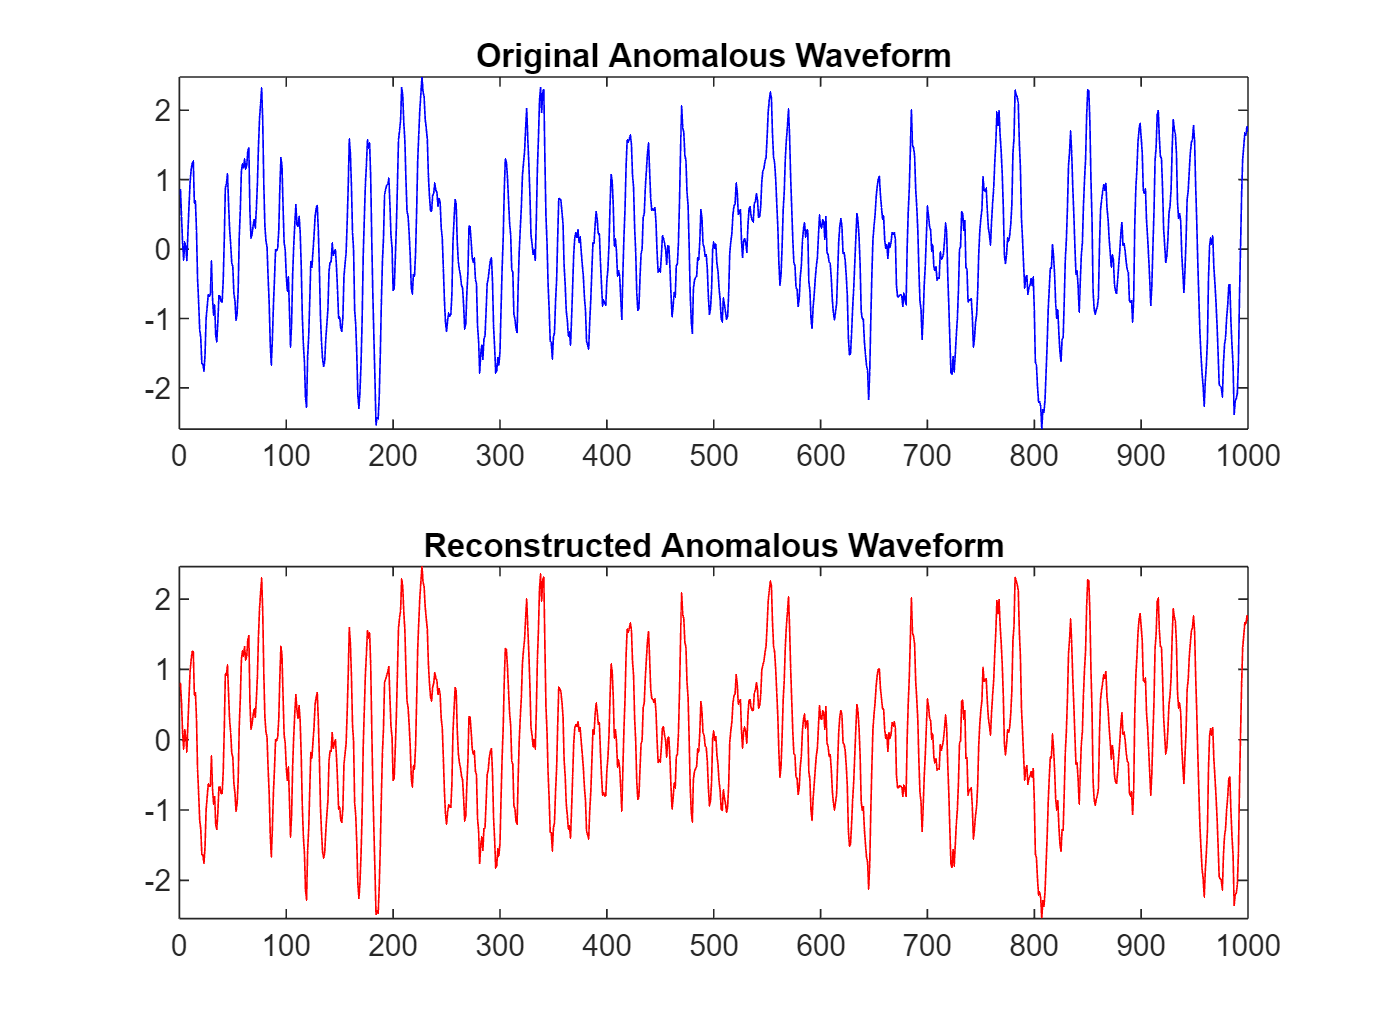


% Visualize a few anomalous reconstructions
sampleIdxtest = 5;

original = testHealthyData(sampleIdxtest, :);
reconstructed = predictedHealthy(sampleIdxtest, :);

figure;
subplot(2,1,1);
plot(original, 'b');
title("Original Anomalous Waveform");

subplot(2,1,2);
plot(reconstructed, 'r');
title("Reconstructed Anomalous Waveform");

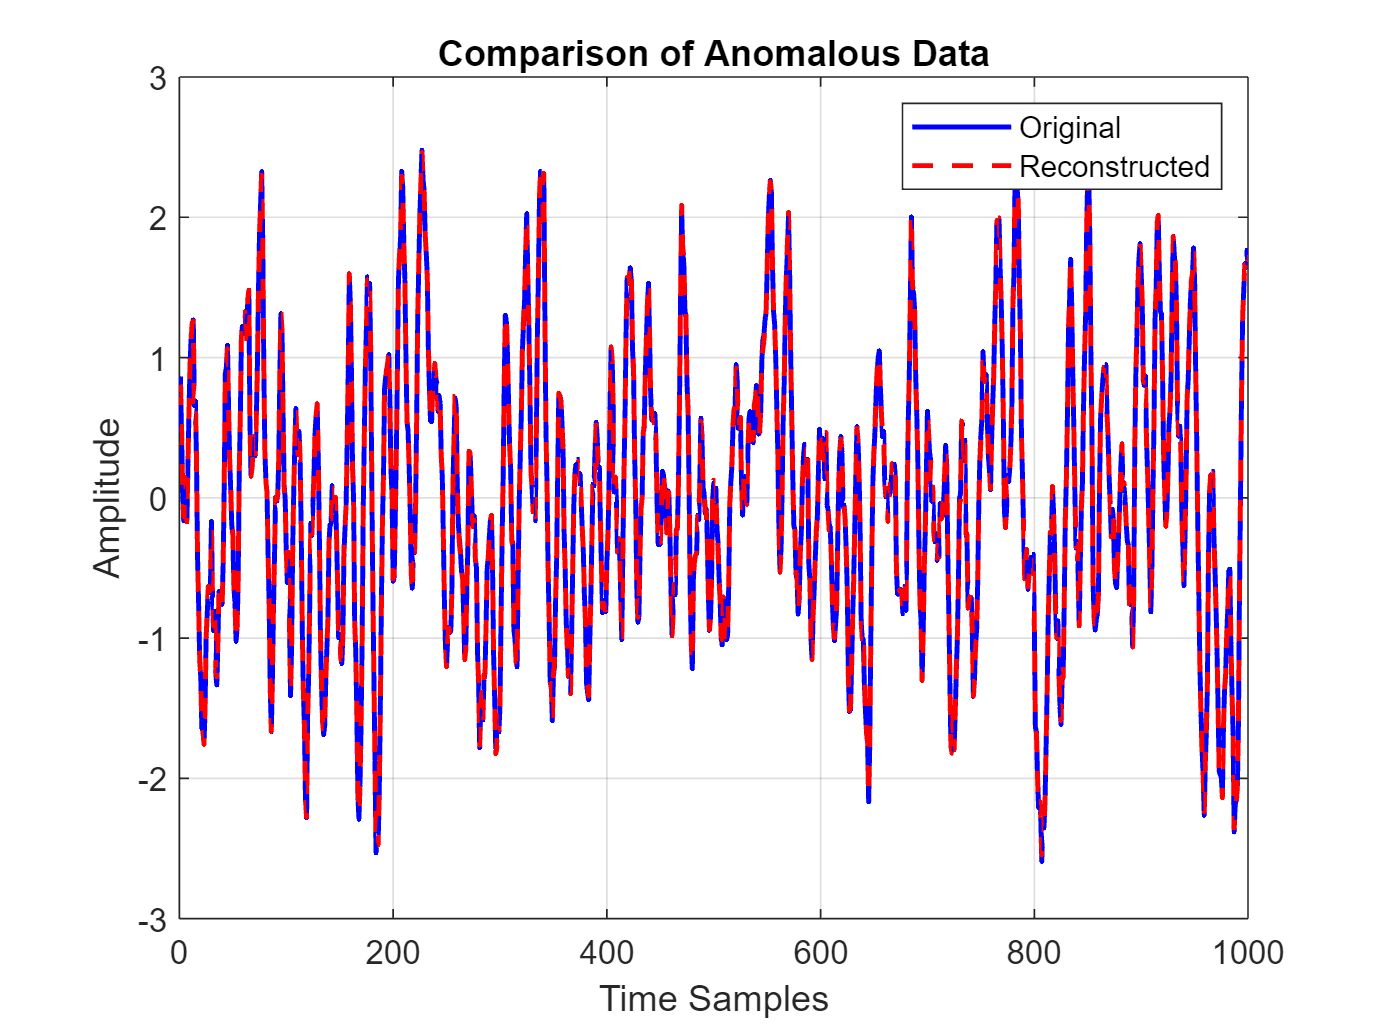


figure;
plot(original, 'b', 'LineWidth', 1.5); hold on;
plot(reconstructed, 'r--', 'LineWidth', 1.5);
legend("Original", "Reconstructed");
title("Comparison of Anomalous Data");
xlabel("Time Samples");
ylabel("Amplitude");
grid on;